# TEMPOmap 16Gene merge_spots

addpath('Z:/Documents/starmap_colab/Pipeline/');
addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:\Data\Processed\2022-09-12-Rena-HeLa16Gene\output\';

## Load TileConfiguration

current_well = 'Area_7'

current_well = 'Area_7'

rotation_degree = -90;

% merge dots 
stitch_file = fullfile(input_path,  '2022-09-16-stitching/rotated_seq_DAPI/', current_well, "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y', 'z'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));
TileConfiguration.z = int32(fix(TileConfiguration.z));

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x      y     z
    ____    ____    __    _

    253        0     0    0
    260     1833     4    3
    267     3659    10    5
    274     5496    13    1
    281     7319    18    2



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));
offset_z = abs(min(TileConfiguration.z));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;
TileConfiguration.z = TileConfiguration.z + offset_z + 1;

## Merge dots

% load stitched dapi image
dapi_file = fullfile(input_path, "2022-09-16-stitching/rotated_seq_DAPI/", current_well, append(current_well,'.tif'))

dapi_file = "Z:\Data\Processed\2022-09-12-Rena-HeLa16Gene\output\2022-09-16-stitching\rotated_seq_DAPI\Area_7\Area_7.tif"

% dapi_img = imread_big(dapi_file);
dapi_3d = imread_big(dapi_file);
dapi_max = max(dapi_3d, [], 3);

% create empty holders 
merged_points = int32([]);
merged_reads = {};
merged_region = [];

upd = textprogressbar(size(TileConfiguration,1), 'updatestep', 2);

Completed [                    ]   0% --:--:--

for r=1:size(TileConfiguration,1)
% for r=1:3
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile) 
    curr_dot_file = fullfile(input_path, "2022-09-14-spot-finding", curr_position_dir, "goodPoints_max3d.mat");
    if isfile(curr_dot_file)
        load(curr_dot_file); 
        
        %% a twist here: there are position folders that does not contain .mat file
        if ~isempty(tile_goodSpots)
             if rotation_degree == -90
                % rotate 90 c
                temp = tile_goodSpots;
                tile_goodSpots(:, 2) = temp(:, 1);
                tile_goodSpots(:, 1) = 2049 - temp(:, 2);
             end
            
            tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);    
            % construct dots region
            current_min = min(tile_goodSpots, [], 1);
            current_max = max(tile_goodSpots, [], 1);
            if current_max(1) > size(dapi_max, 2)
                % fprintf("1")
                current_max(1) = size(dapi_max, 2);
                toKeep = tile_goodSpots(:, 1) <= current_max(1);
                tile_goodSpots = tile_goodSpots(toKeep, :);
                tile_goodReads = tile_goodReads(toKeep);
            
            else if current_max(2) > size(dapi_max, 1)
                    % fprintf("2")
                    current_max(2) = size(dapi_max, 1);   
                    toKeep = tile_goodSpots(:, 2) <= current_max(2);
                    tile_goodSpots = tile_goodSpots(toKeep, :);
                    tile_goodReads = tile_goodReads(toKeep);
                  
            end
            end
            current_region = zeros(size(dapi_max));
            current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
            % current_region(y+1:current_max(2), x+1:current_max(1)) = 1;
            
            % merge dots 
            if isempty(merged_region)
                merged_region = current_region;
            else
                current_overlap = merged_region & current_region;
                merged_region = merged_region | current_region;
                current_region = current_region - current_overlap; 
                
                temp_cell = num2cell(tile_goodSpots, 2); 
                current_lindex = cellfun(@(x) sub2ind([size(dapi_3d)], x(2), x(1)), temp_cell);
                current_logical = logical(current_region(current_lindex));
                tile_goodSpots = tile_goodSpots(current_logical, :);
                tile_goodReads = tile_goodReads(current_logical);
            end
            
            % save current 
            merged_points = [merged_points; tile_goodSpots]
            merged_reads = [merged_reads; tile_goodReads];
        end
    end
    upd(r);
end

curr_position_dir = "Position253"

merged_points = 11028×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position260"

merged_points = 27117×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [                    ]   4% 00:00:29

curr_position_dir = "Position267"

merged_points = 48984×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position274"

merged_points = 72684×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=                   ]   9% 00:00:34

curr_position_dir = "Position281"

merged_points = 94422×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position288"

merged_points = 115540×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [==                  ]  14% 00:00:34

curr_position_dir = "Position254"

merged_points = 126017×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position261"

merged_points = 140792×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [===                 ]  19% 00:00:32

curr_position_dir = "Position268"

merged_points = 158987×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position275"

merged_points = 176646×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [====                ]  23% 00:00:31

curr_position_dir = "Position282"

merged_points = 201014×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position289"

merged_points = 221277×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=====               ]  28% 00:00:30

curr_position_dir = "Position255"

merged_points = 232973×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position262"

merged_points = 253615×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [======              ]  33% 00:00:28

curr_position_dir = "Position269"

merged_points = 264333×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position276"

merged_points = 284642×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=======             ]  38% 00:00:26

curr_position_dir = "Position283"

merged_points = 306504×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position290"

merged_points = 325347×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [========            ]  42% 00:00:24

curr_position_dir = "Position256"

merged_points = 342309×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position263"

merged_points = 353839×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=========           ]  47% 00:00:22

curr_position_dir = "Position270"

merged_points = 364576×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position277"

merged_points = 379261×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [==========          ]  52% 00:00:20

curr_position_dir = "Position284"

merged_points = 397671×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position291"

merged_points = 415767×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [===========         ]  57% 00:00:18

curr_position_dir = "Position257"

merged_points = 432191×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position264"

merged_points = 446719×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [============        ]  61% 00:00:16

curr_position_dir = "Position271"

merged_points = 456853×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position278"

merged_points = 472029×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=============       ]  66% 00:00:14

curr_position_dir = "Position285"

merged_points = 488665×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position292"

merged_points = 507169×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [==============      ]  71% 00:00:12

curr_position_dir = "Position258"

merged_points = 522849×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position265"

merged_points = 535755×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [===============     ]  76% 00:00:10

curr_position_dir = "Position272"

merged_points = 548689×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position279"

merged_points = 563441×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [================    ]  80% 00:00:08

curr_position_dir = "Position286"

merged_points = 575138×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position293"

merged_points = 590817×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=================   ]  85% 00:00:06

curr_position_dir = "Position259"

merged_points = 599348×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position266"

merged_points = 612004×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [==================  ]  90% 00:00:04

curr_position_dir = "Position273"

merged_points = 627541×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position280"

merged_points = 637709×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [=================== ]  95% 00:00:02

curr_position_dir = "Position287"

merged_points = 649017×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


curr_position_dir = "Position294"

merged_points = 665859×3 int32 matrix
   1497    952     22
   1210    477     23
   1644    478     23
   1416    760     23
   1347    803     23
   1726    809     23
   1737    880     23
   1836    942     23
   1301    947     23
   1197    951     23


Completed [====================] Done. [42 seconds]


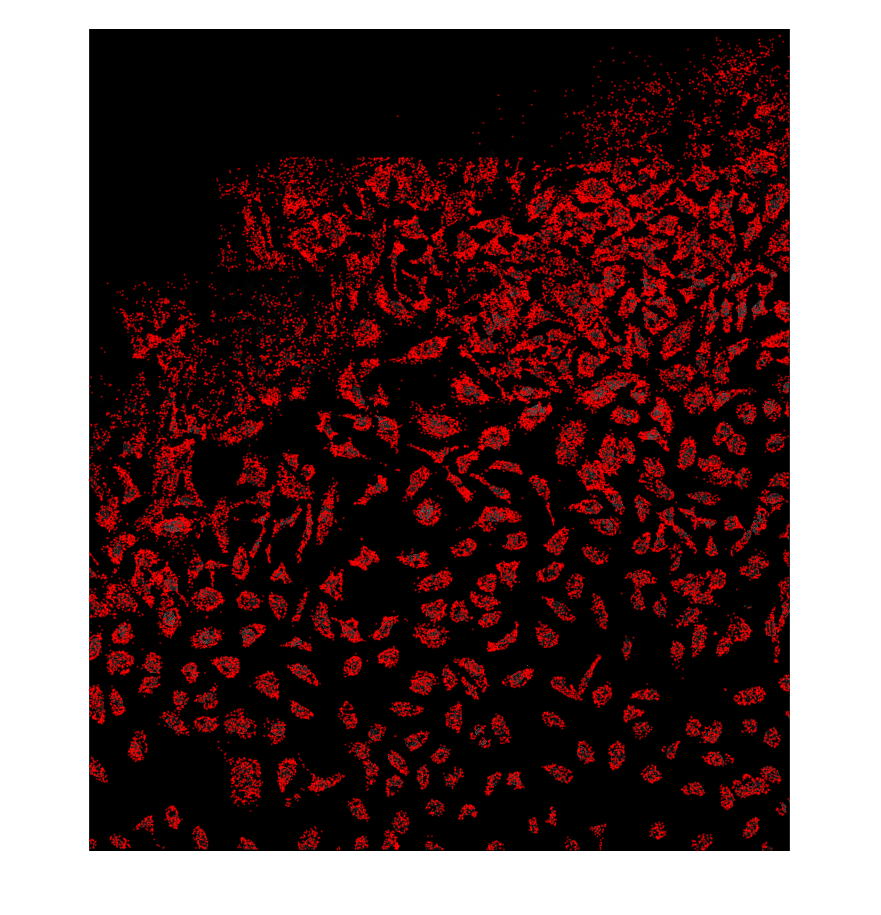


merged_points(:,1) = merged_points(:,1) - 1;
merged_points(:,2) = merged_points(:,2) - 1;
merged_points(:,3) = merged_points(:,3) - 1;

z = 20;
plot_centroids(merged_points(merged_points(:, 3) == z, :), dapi_3d(:,:,z), 1)

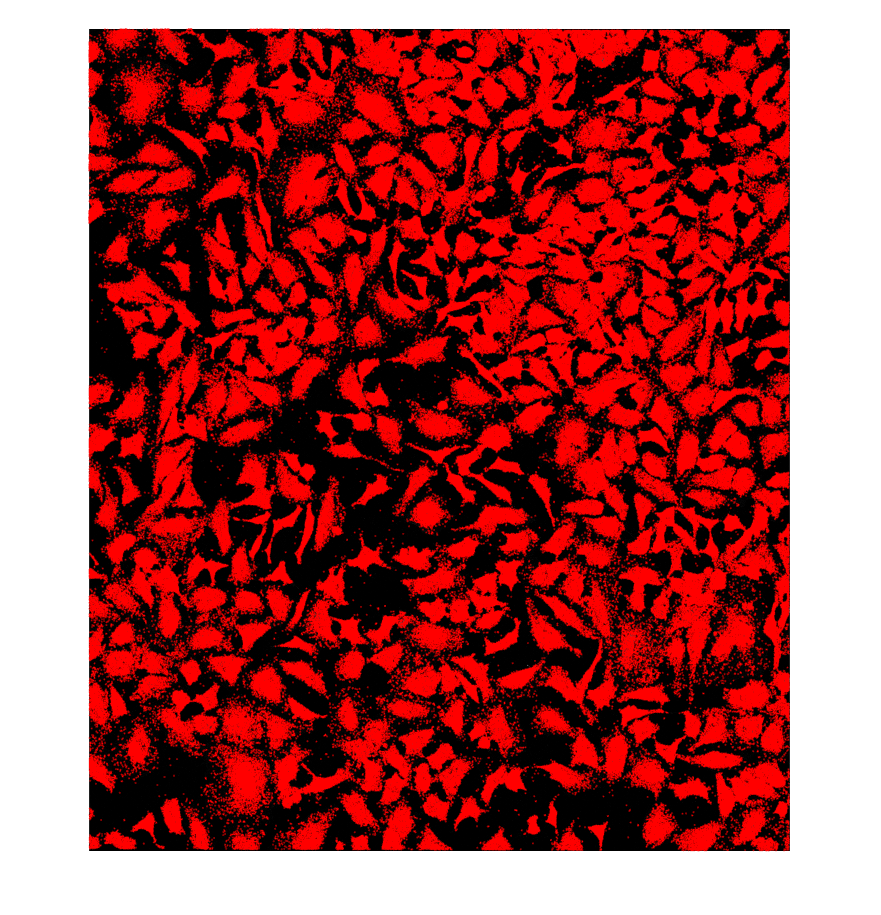


plot_centroids(merged_points, dapi_max, 1)

## output

spot_out_path = fullfile(input_path, '2022-09-22-merged-points', current_well);
if ~exist(spot_out_path, 'dir')
    mkdir(spot_out_path)
end
save(fullfile(input_path, '2022-09-22-merged-points', current_well, 'merged_goodPoints.mat'), "merged_points", "merged_reads");